img = imread("test_imgs\img2.png");

hd_resolution = [720 1280];
img = imresize(img, hd_resolution);

% Wybrane punkty do wycięcia obrazu z pespektywy lotu ptaka
TL = [576 401];
BR = [1100 601];

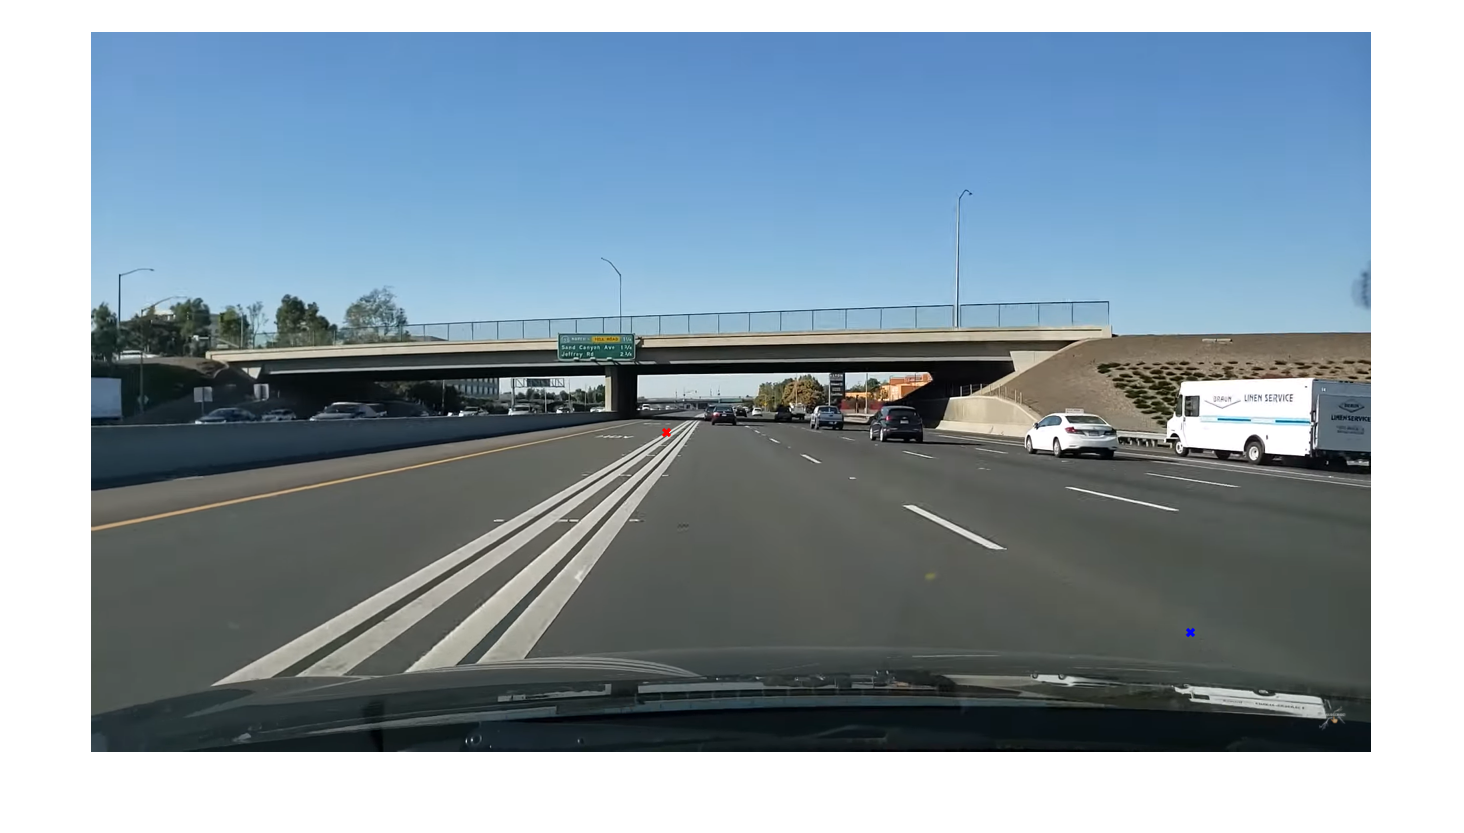

%Przedstawienie wybranych punktów na zdjęciu
figure;
imshow(img);
hold on
plot(TL(1),TL(2),'x','LineWidth',2,'Color','red');
plot(BR(1),BR(2),'x','LineWidth',2,'Color','blue');
hold off

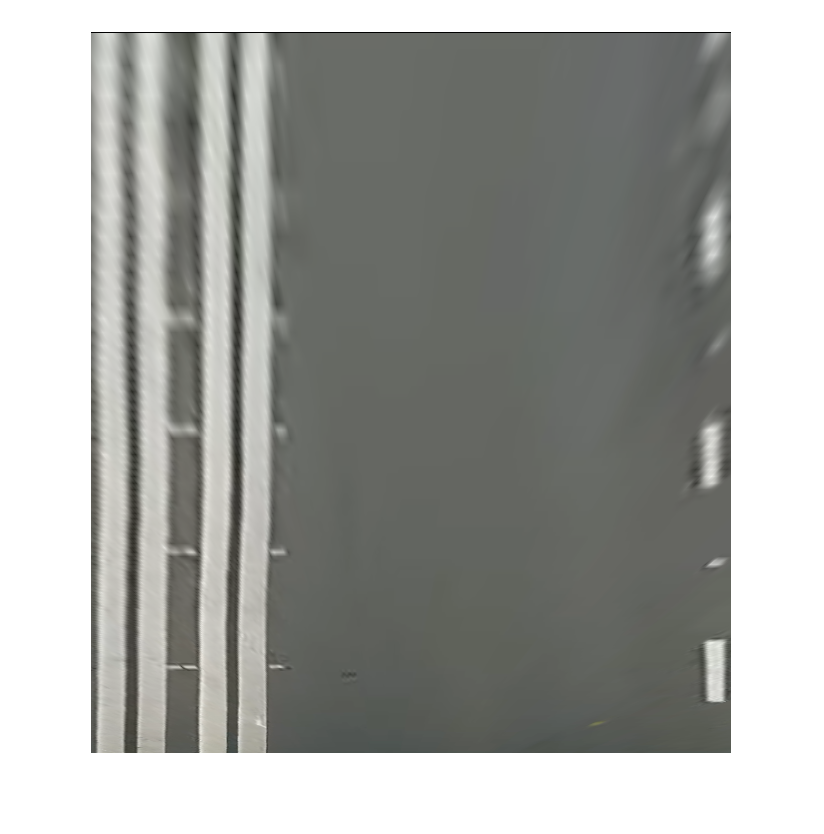

[img_cut, H] = cut_img_birds_eye_view(img,TL,BR);
figure;
imshow(img_cut)